Constants

clear all;
num_symbols = 8*1024; 
symbol_rate = 32e9;
time_step = 1/symbol_rate;
upsampling = 2;
sample_rate = upsampling*symbol_rate;
num_samples = upsampling*num_symbols;
Ts = 1/sample_rate;

symbols_b = randi([0 1],1,num_symbols);
symbols_q = randi([0 3],1,num_symbols);

Modulation & Upsampling

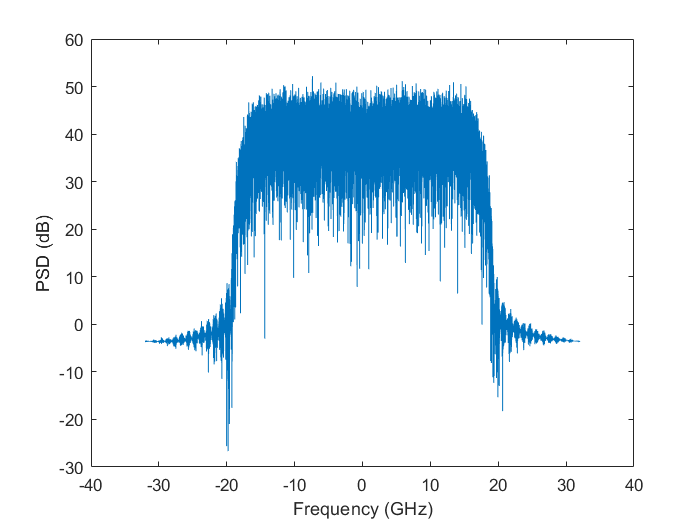

%BPSK %QPSK
bpsk_mod = pskmod(symbols_b,2,0,'gray');
qpsk_mod = pskmod(symbols_q,4,pi/4,'gray');

UPS_filter = comm.RaisedCosineTransmitFilter("FilterSpanInSymbols",32,"OutputSamplesPerSymbol",upsampling);
DPS_filter = comm.RaisedCosineReceiveFilter("FilterSpanInSymbols",32,"InputSamplesPerSymbol",upsampling,"DecimationFactor",upsampling);

upsampled_bpsk = UPS_filter(bpsk_mod')';
upsampled_qpsk = UPS_filter(qpsk_mod')';

Pxx = ifftshift(fft(upsampled_qpsk).*conj(fft(upsampled_qpsk)));
[~,f] = periodogram(upsampled_qpsk,[],[],sample_rate,'centered');
plot(f/1e9,10*log10(Pxx));
xlabel("Frequency (GHz)");
ylabel("PSD (dB)");


% matched_scope = dsp.SpectrumAnalyzer("SampleRate",symbol_rate,"NumInputPorts",2,"ChannelNames",{"BPSK","QPSK"},"ShowLegend",true);
% raised_cosine_scope = dsp.SpectrumAnalyzer('SampleRate',sample_rate,"NumInputPorts",2,"ChannelNames",{"BPSK","QPSK"},"ShowLegend",true);
% 
% matched_scope(bpsk_mod',qpsk_mod');
% raised_cosine_scope(upsampled_bpsk',upsampled_qpsk');

Phase Noise

linewidth = 0;
variance = 2*pi*linewidth*Ts;    
phase_noise = randn(1,num_samples);
    
random_walk_phase_noise = cumsum(sqrt(variance)*phase_noise);
          
noisy_bpsk = upsampled_bpsk.*exp(1j*random_walk_phase_noise);
noisy_qpsk = upsampled_qpsk.*exp(1j*random_walk_phase_noise);

Adaptive Equalisation (LMS)  (Attempt CMA algorithm)

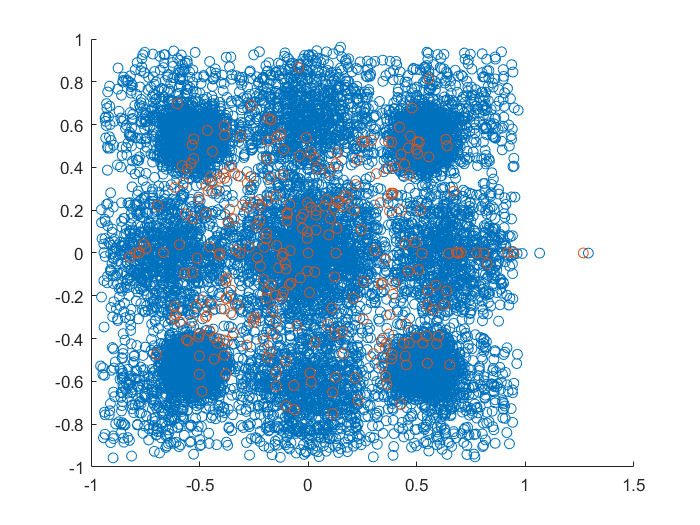

d = upsampled_qpsk'; %Desired Output
x = noisy_qpsk'; %Received Input

h_taps = 16; %Small Value, power of 2

h = zeros(h_taps,1);
h(8) = 1;  
% Train symbols to get h
training_size = 300;
mu = 0.002;

for i = h_taps:training_size
    
    temp = x(i:-1:i-h_taps+1) ; %From 8th down to 1st
    
    hx(i) = h.' * temp;
    
    e(i) = d(i) - hx(i);
    
    
    h = h + mu*e(i)*conj(temp);
end    

figure
hold on
scatter(real(noisy_qpsk),imag(noisy_qpsk));
scatter(real(hx),imag(hx));

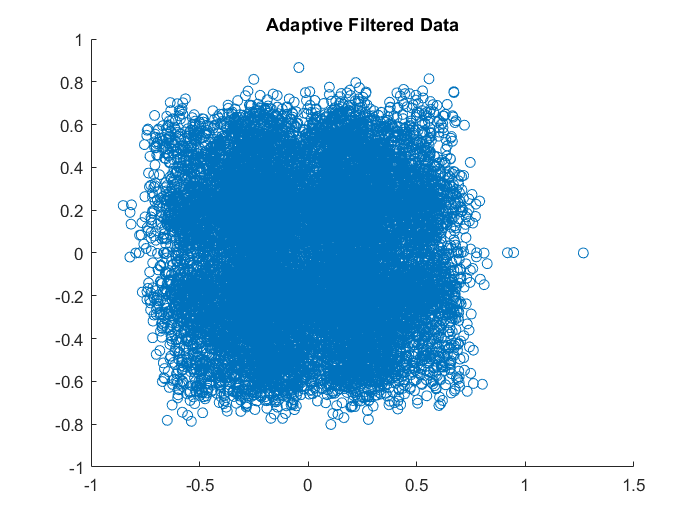


for i =  training_size+1 : num_samples
    
	temp = x(i:-1:i-h_taps+1) ;
    
    hx(i) = h' * temp ;
    
    e(i) = d(i) - hx(i) ;
end


figure
scatter(real(hx),imag(hx));
title("Adaptive Filtered Data");

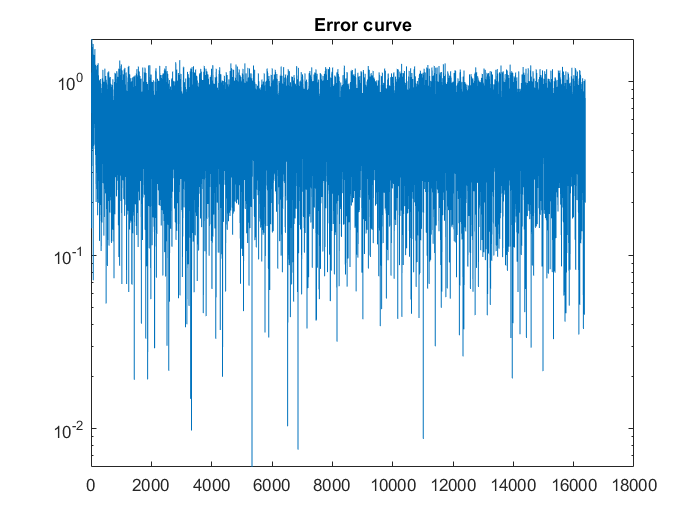


figure
semilogy((abs(e))) ;
title('Error curve');

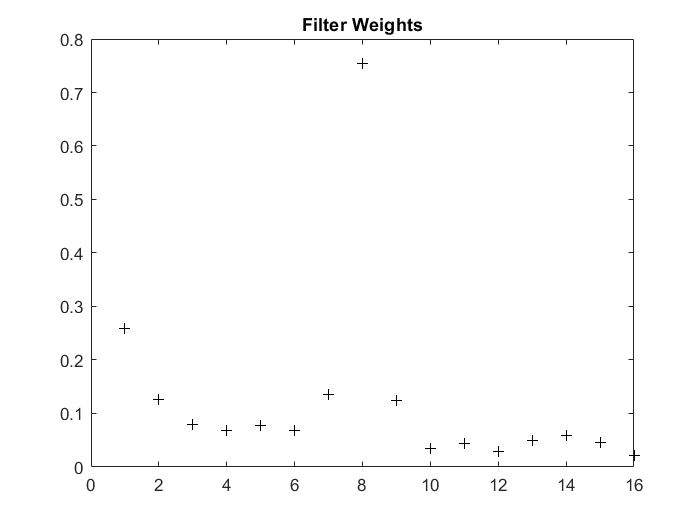


figure
plot(abs(h),'k+');
title("Filter Weights");



downsampled_qpsk = DPS_filter(hx')';
demoded_qpsk = pskdemod(downsampled_qpsk,4,pi/4,'gray');
[a,b] = alignsignals(symbols_q,demoded_qpsk,[],"truncate"); 
[~,BER] = biterr(a,b);

(Check if this is required)

Chromatic Dispersion

% %Define angular frequency vector
% 
% f_up = (0:(num_samples)/2-1);
% f_down = (-(num_samples)/2:-1);
% fs = [f_up f_down]*sample_rate/num_samples;
% w = 2*pi*fs;
% T = 1/sample_rate; %Sampling Period
% 
% %Define Chromatic Dispersion Typical Parameters
% z = 500e3; % m
% D = 16*10^-6; % s/m/m
% lambda = 1550*10^-9; % m
% c = 299792458; % m/s
% 
% K = (D*lambda^2*z)/(4*pi*c*T^2); 
% 
% chromatic_dispersion_FIR = exp(-1j*K.*(w.^2)*T^2);
% 
% %Does this does cyclic operations instead of linear operations -- is this relevant?                      
% CD_bpsk = ifft(chromatic_dispersion_FIR.*fft(upsampled_bpsk)); 
% CD_qpsk = ifft(chromatic_dispersion_FIR.*fft(upsampled_qpsk));
% 
% 
% % figure
% % scatter(real(CD_bpsk),imag(CD_bpsk),'*');
% % title("BPSK Symbols with Chromatic Dispersion");
% % xlabel("In-phase Amplitude");
% % ylabel("Quadrature Amplitude");
% % figure
% % scatter(real(CD_qpsk),imag(CD_qpsk),'*','MarkerEdgeColor','red','MarkerFaceColor','red');
% % title("QPSK Symbols with Chromatic Dispersion");
% % xlabel("In-phase Amplitude");
% % ylabel("Quadrature Amplitude");